# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 09-Dec-2020 16:46:18

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 53);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A1:BA38";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26", "VarName27", "VarName28", "VarName29", "VarName30", "VarName31", "VarName32", "VarName33", "VarName34", "VarName35", "VarName36", "VarName37", "VarName38", "VarName39", "VarName40", "VarName41", "VarName42", "VarName43", "VarName44", "VarName45", "VarName46", "VarName47", "VarName48", "VarName49", "VarName50", "VarName51", "VarName52", "VarName53"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
Non_sevVsSev_Plasma_matlab_input = readtable("/MATLAB Drive/Non-sevVsSev_Plasma_matlab_input.xlsx", opts, "UseExcel", false);

numberTable = Non_sevVsSev_Plasma_matlab_input(:,1:53);
numberArray = table2array(numberTable);
s1 = zeros(51,1);
s2 = zeros(51,1);
s3 = zeros(51,1);
p=0;
%setting up correlation
%correlation with median of COVID-19 Non-severe samples
for j = 1:51
    s1(j) = corr(numberArray(:,j),numberArray(:,52),"type","Pearson");
    s2(j) = corr(numberArray(:,j),numberArray(:,52),"type","Kendall");
    s3(j) = corr(numberArray(:,j),numberArray(:,52),"type","Spearman");
end
h1 = zeros(51,1);
h2 = zeros(51,1);
h3 = zeros(51,1);

%setting up correlation 
%correlation with COVID-19 Severe sample
for j = 1:51
    h1(j) = corr(numberArray(:,j),numberArray(:,53),"type","Pearson");
    h2(j) = corr(numberArray(:,j),numberArray(:,53),"type","Kendall");
    h3(j) = corr(numberArray(:,j),numberArray(:,53),"type","Spearman");
end
%Normalisation
%absolute mean of set-1 & set-2
sum1 =0;
sum2 =0;
sum3 =0;
add1 =0;
add2 =0;
add3 =0;
for i = 1:51
    sum1 = sum1 + s1(i);
    sum2 = sum1 + s2(i);
    sum3 = sum1 + s3(i);
    add1 = add1 + h1(i);
    add2 = add2 + h2(i);
    add3 = add3 + h3(i);
end
sum1 = sum1/51;
sum2 = sum3/51;
sum3 = sum3/51;
add1 = add1/51;
add2 = add2/51;
add3 = add3/51;
s1 = s1/sum1;
s2 = s2/sum2;
s3 = s2/sum3;
h1 = h1/add1;
h2 = h2/add2;
h3 = h3/add3;
%Difference of Normalised set-1 with set-2
%defining predictor
D = zeros(51,3);
D(:,1) = s1 - h1;
D(:,2) = s2 - h2;
D(:,3) = s3 - h3;
failed = 0;
passed = 0;
Accuracy = zeros(3,1);
for j = 1:3
for i = 1:51
    if(D(i,j)>0 && i<=18)
        "NON-SEV SAMPLE & PASSED";
        passed = passed + 1;
    end
    if(D(i,j)<0 && i<=18)
        "NON-SEV SAMPLE & FAILED";
        failed = failed + 1;
    end
    if(D(i,j)<0 && i>18)
        "SEV SAMPLE & PASSED";
        passed = passed + 1;
    end
    if(D(i,j)>0 && i>18)
        "SEV SAMPLE & FAILED";
        failed = failed + 1;
    end
end
passed;
failed;
Accuracy(j) = passed/(passed + failed);
Accuracy(j) = Accuracy(j)*100;
passed = 0; failed = 0;
end
Accuracy

Accuracy =    74.5098
   80.3922
   72.5490


%plot
for i = 1:51
    x(i) = i;
    y(i) = 0;
end
scatter(x,s2,'*')
hold on
scatter(x,h2,'*')
hold on
scatter(x,D(:,2),'*')
legend('set-1','set-2','Nomalized set-1-set-2','location',"best")
hold on
p = plot(x,y)

p =   Line with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              YData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
              ZData: [1×0 double]

  Show all properties


hold off
xlabel('sample count')
ylabel('Correlation with Non-sev & sev Median')
title('Accuracy 80.39% with Kendall correlation');

yL = get(gca,'YLim');
q = line([18 18],yL,'Color','r');
p.Annotation.LegendInformation.IconDisplayStyle = 'off';
q.Annotation.LegendInformation.IconDisplayStyle = 'off';
str = {'Predicted Non-severe'}

str = 1×1 cell array
    {'Predicted Non-severe'}


text(0.1,0.4,str)
str = {'Predicted Severe samples'}

str = 1×1 cell array
    {'Predicted Severe samples'}


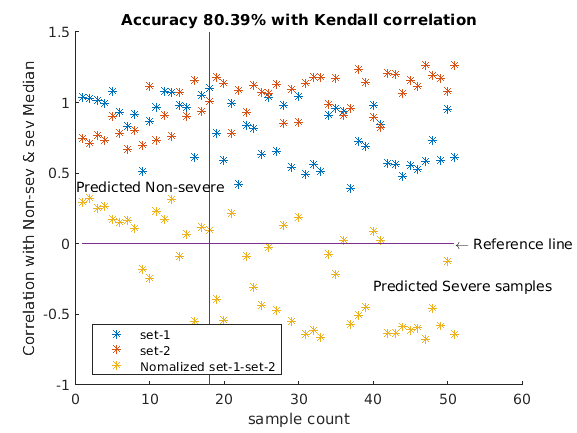

text(40,-0.3,str)
text(51,0,'\leftarrow Reference line')
xlim([0.0 60.0])
ylim([-1.00 1.50])

## Clear temporary variables

clear opts